# DeepInterpolation - Tiny Ephys Inference Example

This example imports and uses the deep interpolation model in MATLAB for tiny ephys sample data.

## Run setup for initialization of path

deepinterp.setup();

## Import and Assemble Model

Import the trained model.

deepinterpnet = deepinterp.getPretrainedModel('Ephys-Neuropixels_Phase_3a_1050');

Importing the saved model...
Translating the model, this may take a few minutes...


Finished translation. Assembling network...
Import finished.


## Analyze Network

Optionally analyze the network

if false
    analyzeNetwork(deepinterpnet)
end


## Read Sample Ephys Data

Examine the file to determine how many data frames are present. 

raw_data = memmapfile('ephys_tiny_continuous.dat2','Format','int16');
nb_probes = 384; % Number of electrodes

Open the file again following the correct shape of the data. A Neuropixels electrode has 384 sites. This example data is from a Phase 3a electrode that has a checkerboard pattern with two offset "rows" (that is, the layout of the file is [total_frames x 192 x 2]).

total_frame_per_movie = fix(length(raw_data.Data)/(nb_probes));

shape = [total_frame_per_movie, fix(nb_probes / 2), 2];
% shape = [nb_probes, 2, total_frame_per_movie]; % final shape of the data [384,2,x]

% Format the data to match the dimensions of a neuropixels probe
raw_data = memmapfile('ephys_tiny_continuous.dat2','Format',{'int16', shape,'x'});
ephys = permute(raw_data.Data.x,[2 3 1]); % re-arrange so that frames are in the third dimension
ephys = single(ephys); % convert to floating point, single precision
% subtract mean and divide by standard deviation
ephys = (ephys - mean(ephys(:))) / std(ephys(:));
% let's only operate on a subset so the example works fast without GPUs
subset = 1:300;
ephys = ephys(:,:,subset);

## We reorganize to follow true geometry of probe for convolution 

#### (Fig. 3 [https://doi.org/10.1101/2020.10.15.341602](https://doi.org/10.1101/2020.10.15.341602)) 

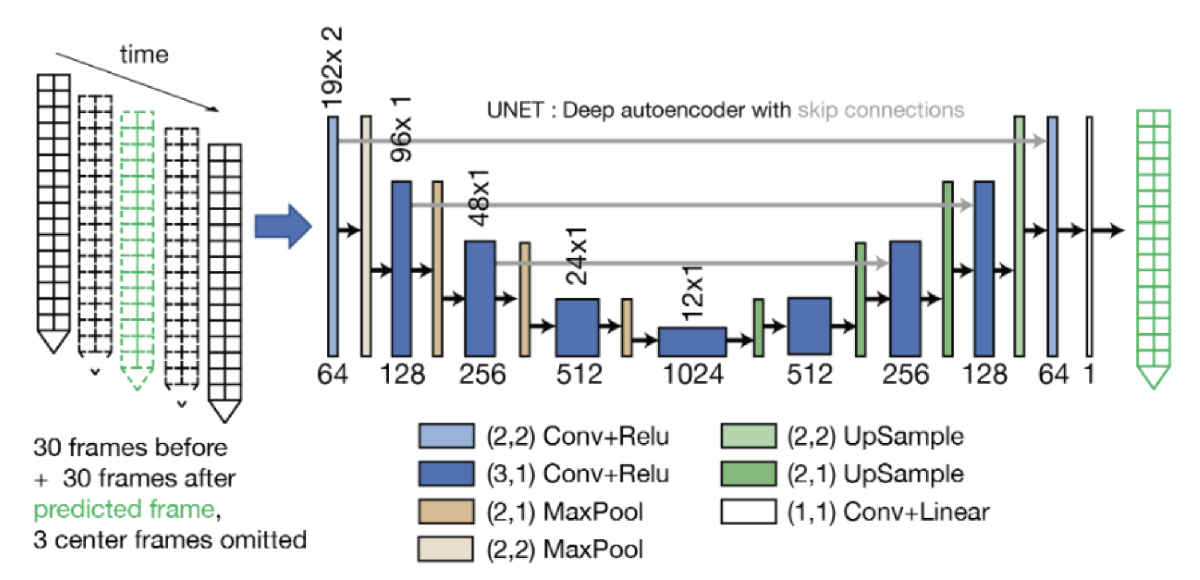

Neuropixels Phase 3a probes have a checkerboard pattern.  On one column (say the left), the first electrode pad occupies a certain position. To its right, there is no electrode immediately adjacent but instead it is offset lower down on the probe. The electrode array continues in this pattern. The authors transformed the data from a frame size of [192 x 2] to [384 x 2], with zeros filled in where no electrodes are present, to match the geometry of the electrode. 

ephys_transformed = deepinterp.NPframe2checkerboard(ephys);

## Make Inference

output_transformed = deepinterpnet.interp(ephys_transformed);
output_ephys = deepinterp.NPcheckerboard2frame(output_transformed);

## Plot inference results

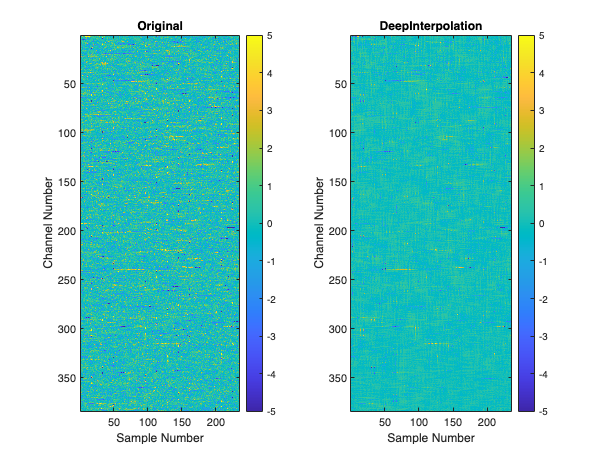

% now plot as an image
ephys_permute = permute(ephys,[2 1 3]);
ephys_plot = reshape(ephys_permute,nb_probes,size(ephys,3));
output_plot = reshape(permute(output_ephys,[2 1 3]),nb_probes,size(ephys,3));

hFig = figure; 
hAxRef = subplot(1,2,1); 
hImRef = imagesc(ephys_plot(:,33:end-33)); % plot only the interpolated data not the edges 
clim([-5 5]);
xlabel('Sample Number')
ylabel('Channel Number')
title('Original')
colorbar
hAx = subplot(1,2,2); 
hIm = imagesc(hAx,output_plot(:,33:end-33)); 
clim([-5 5]);
colorbar;
xlabel('Sample Number')
ylabel('Channel Number');
title('DeepInterpolation');
linkaxes([hAxRef hAx]);

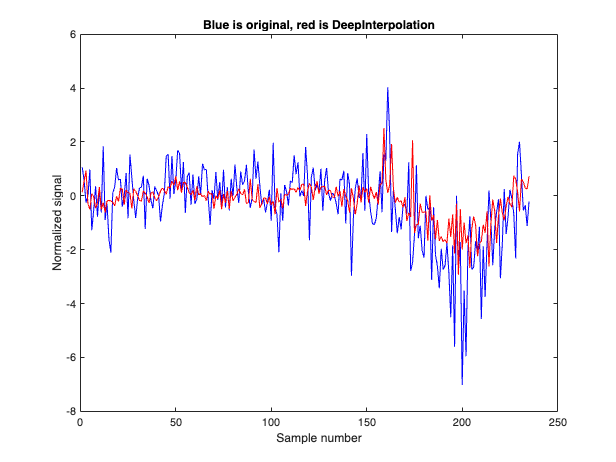

% show a trace

figure;
plot(ephys_plot(74,33:end-33),'b');
hold on;
plot(output_plot(74,33:end-33),'r');
xlabel('Sample number');
ylabel('Normalized signal');
title(['Blue is original, red is DeepInterpolation']);